# Image Analysis for Biometric features

Identify points in a frame that correspond the center point of a fish's head by analyzing the intensity characteristics of the larvae. The solution should not depend on threshold values that are manually determined. Investigate the accuracy of your determinations.

## Acquiring images from file

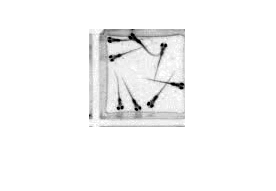

folder = '.\zebraFish\frames_grey';
filePattern = fullfile(folder, '*.png');
theFiles = dir(filePattern);
numimages = length(theFiles);

for i=1:1
    baseFileName = theFiles(i).name;
    fullFileName = fullfile(theFiles(i).folder, baseFileName);
    img = imread(fullFileName);
    imshow(img);
end

## Convert Image to Grayscale

Despite the image already being in grayscale, matlab still considers the image an rgb even though the rgb values are all the same within each pixel. Converting the to grayscale gets rid of the rgb and allows the usage of functions that require grayscale images.

grayimg = im2gray(img);

## Cropping out unnecessary pixels.

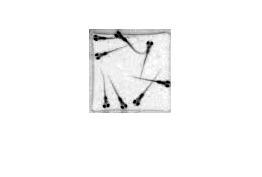

r = images.spatialref.Rectangle([15 96],[3 86]);
cropimg = imcrop(grayimg,r);
imshow(cropimg);

## Examining intensity values

Using imhist function on the grayimg in order to see the intensity value distribution of the grayscale image.

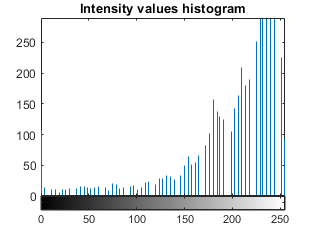

figure('Name','grayimg histogram'), imhist(cropimg);
title("Intensity values histogram");

## Thresholding the image

After using imtool and looking at the histogram to see the intensity characteristics of the fish, we decided to have two images thresholded in different ways.One image is thresheld with the value of zero since the darkest parts of the fish are its body and eyes. This helps to.

level = multithresh(cropimg);
threshimg =  imquantize(cropimg,level);
thrimg = label2rgb(threshimg);
thrimg = im2gray(thrimg);
threshimg = imbinarize(thrimg);
complementImg = imcomplement(threshimg)

complementImg = 84×82 logical array
   1   1   1   1   1   1   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   1   1   1   1   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   1   1   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   1   1   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   1   1   0   0   1   1   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   1   1   1   1   1   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   1   0   0   1   1   1   1   1   1   1   1   1   1   0   0   0   0   0   0   0   0   0   0   0   0   0   1   1   1   1   1   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   1   1   0   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   0   0   0   1   1   1   1   1   1   1   1   1   1   1   1   0   0   0   0   0

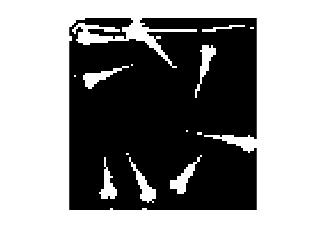

imshow(complementImg);

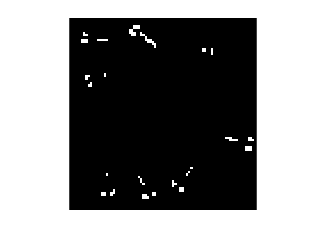


BW = imbinarize(cropimg,0);
BW = imcomplement(BW);
imshow(BW);

## Morphology

Using morpholoy to get rid of noise such as the dots and try to get rid of the line.

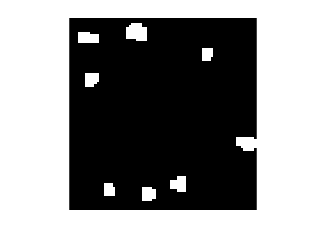

se = strel("square",4 );
openimg = imopen(complementImg, se);
imshow(openimg);

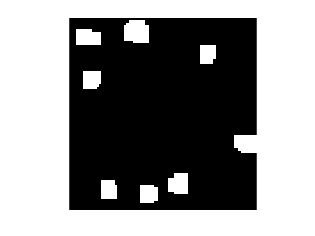


openimg = imdilate(openimg,strel("square", 3));
imshow(openimg);

## 8 Connectivity

Using 8 connectivity to determine what counts as part of the same region.

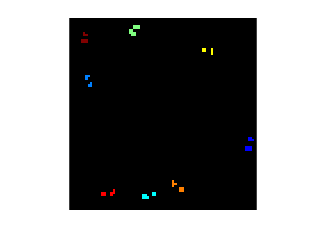

objopenimg = bwconncomp(openimg);
objBW = bwconncomp(BW);

labelopenimg = labelmatrix(objopenimg);
labelBW = labelmatrix(objBW);

bodyimg = objopenimg.PixelIdxList{1};
eyesimg = objBW.PixelIdxList{1};

numbodies = objopenimg.NumObjects;
numeyes = objBW.NumObjects;

for i = 1:numeyes
    for n = 1:numbodies
        if all(ismember(objBW.PixelIdxList{i},objopenimg.PixelIdxList{n}))
            labelBW(objBW.PixelIdxList{i}) = n;
            break;
        elseif n == numbodies
            labelBW(objBW.PixelIdxList{i}) = 0;
        end
    end
end

imshow(label2rgb(labelBW,'jet','k','shuffle'));

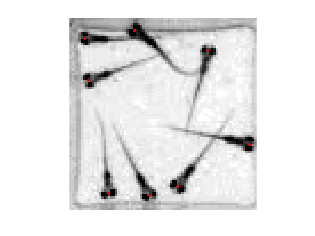


stats = regionprops(labelBW, 'Centroid');
centroids = cat(1,stats.Centroid);

imshow(cropimg)
hold on
plot(centroids(:,1),centroids(:,2),'r.')
hold off

## Intersection of matices

Using the intersection function to find the objects within the first image that are in the same coordinates as the second image. This should get rid of the lines from the body and only keep the eyes as objects.

% intersectionOfimgbw = intersect(labelopenimg, labelBW);

## Edge Detection

Using edge detection to see if it helps separate the fish from the background.

% edgeimg = edge(cropimg, 'approxcanny');
% imshow(edgeimg);
% 
% se = strel("square",2);
% dilimg = imdilate(edgeimg,se);
% imshow(dilimg);
% 
% se = strel("square",2);
% eroimg = imerode(dilimg, se);
% imshow(eroimg);
% dilimg3 = imdilate(edgeimg,se);
% imshow(dilimg3);